# PRÁCTICA 11: Reconocimiento de patrones e inspección

## RECONOCIMIENTO DE PATRONES

Se pretende desarrollar un sistema de reconocimiento de formas para clasificar objetos por su forma. El universo de trabajo está formado por tres tipos de objetos: círculos, triángulos y cuadrados. Para el diseño del sistema se dispone de una muestra controlada formada por tres imágenes, que contienen círculos, triángulos y cuadrados, con distintos tamaños y orientaciones.

Como vector de descriptores para llevar a cabo este sistema de reconocimiento se ha optado por uno bidimensional formado por la media y la desviación típica de la signatura (distancia del centroide al contorno en función del ángulo). El programa ‘CargarMuestra’ es un script que se encarga de leer estas imágenes y de generar los patrones correspondientes de cada una de ellas en tres variables: pci, ptr, pcu; además muestra el espacio de patrones. 

Ejecute dicho programa. Según la distribución de los patrones ¿qué opina sobre los descriptores elegidos?

hol
hol
hol


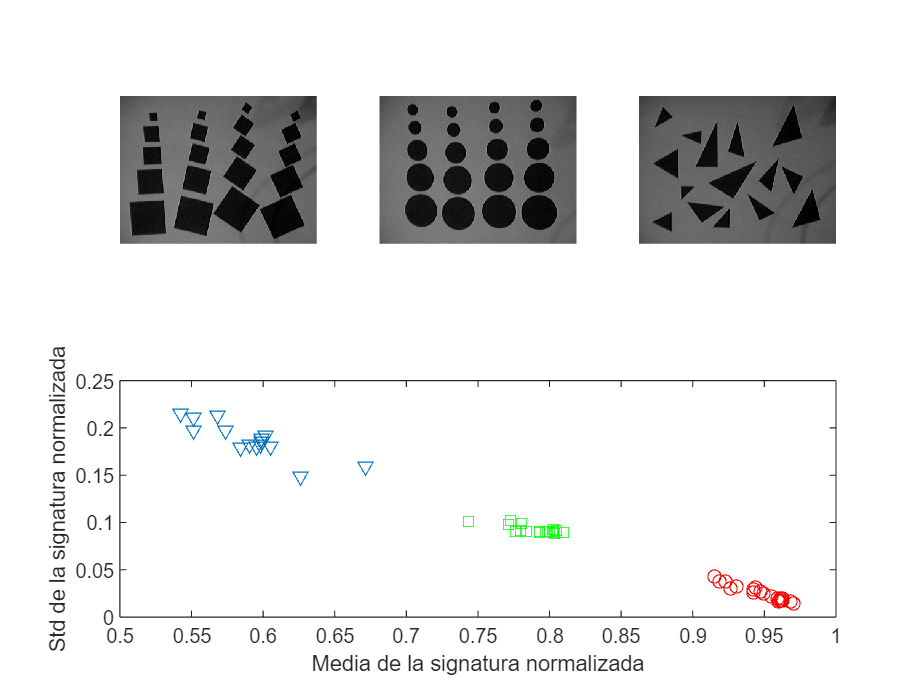

close all;
clear all;
CargarMuestra

El programa perceptron_isa devuelve la ecuación de una recta que separa a dos conjuntos de patrones. Dicho programa posee tres parámetros, que son: patrones de la clase 1, patrones de la clase 2 y el parámetro c para la implementación de incremento fijo. Empleando dicho programa calcule las funciones de decisión necesarias para el caso multiclásico (CASO 2):

- dcutr : función de decisión entre cuadrados y triángulos dtrcu = -dcutr;

- dcuci : función de decisión entre cuadrados y círculos dcicu = -dcicu;

- dtrci : función de decisión entre triángulos y círculos dcitr = -dtrci;

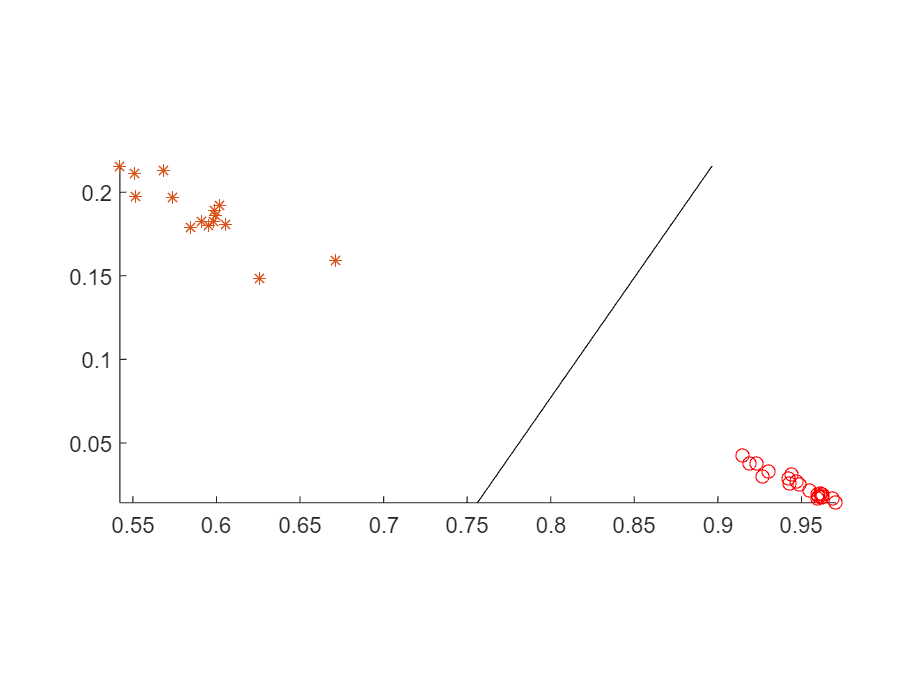

dcitr =     1.3401   -0.9337   -1.0000


dcitr = perceptron_isa(pci, ptr, 1)

dtrci = -dcitr

dtrci =    -1.3401    0.9337    1.0000


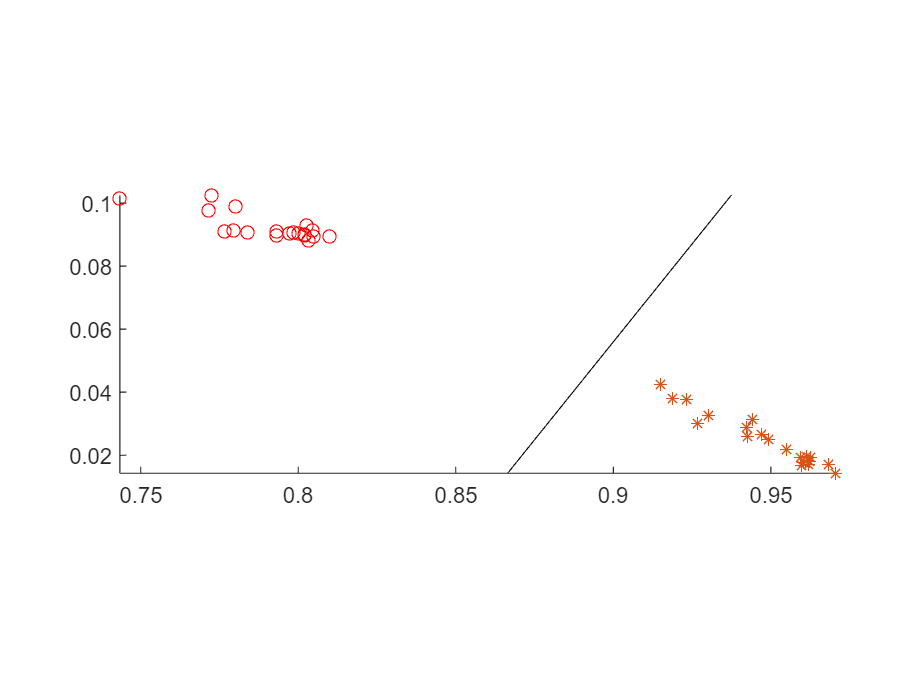

dcuci =    -1.1696    0.9410    1.0000


dcuci = perceptron_isa(pcu, pci, 1)

dcicu = -dcuci

dcicu =     1.1696   -0.9410   -1.0000


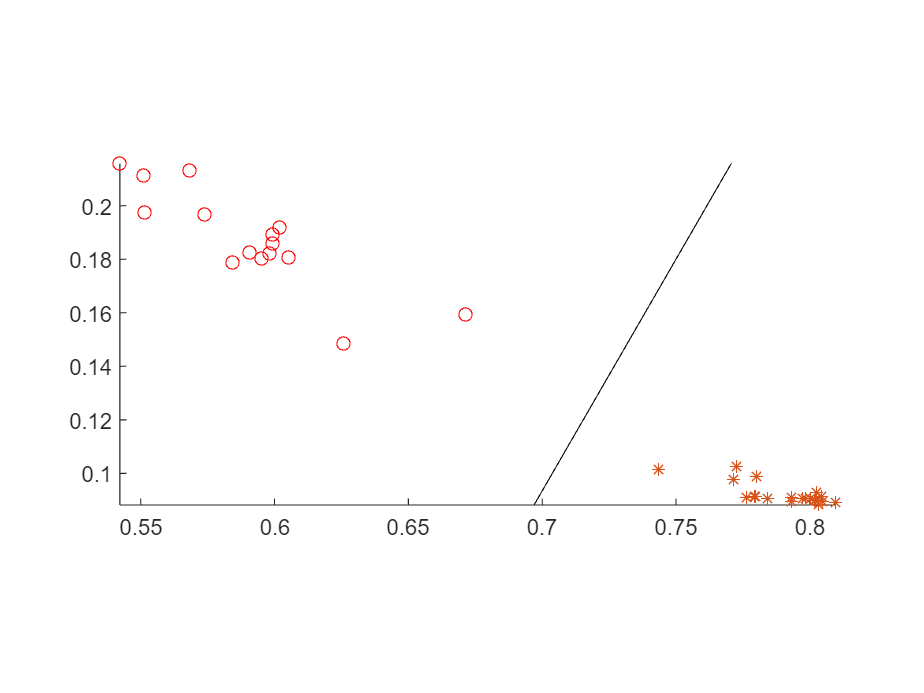

dtrcu =    -1.5479    0.8940    1.0000


dtrcu = perceptron_isa(ptr, pcu, 1)

dcutr = -dtrcu;

Realice un programa que tenga como entrada una imagen que contenga alguna de estas figuras geométricas (p.e, la imagen ‘nueva’) y las funciones de decisión de las tres clases (dcutr, dcuci y dtrci). Dicho programa debe realizar el siguiente proceso:

### Diseño

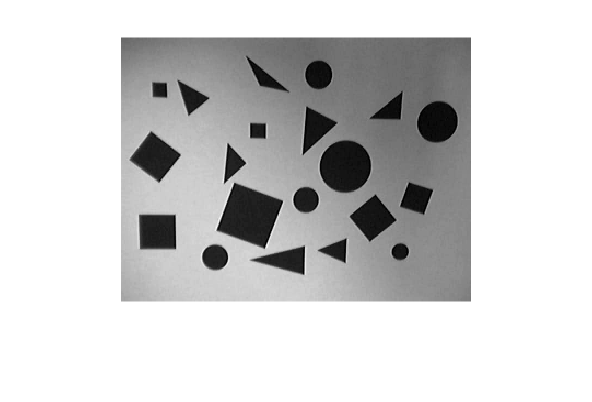

figure
imshow(nueva, [])

#### Segmentar un objeto

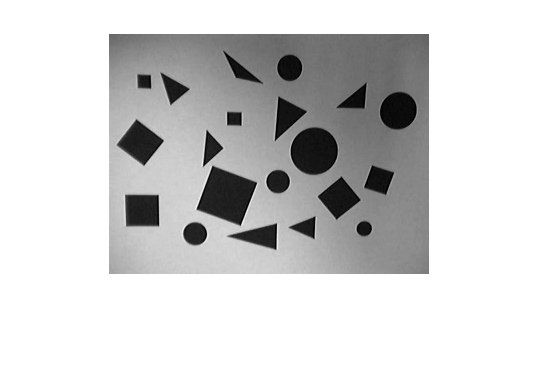

figure
umbral = 40;
c1 = vercre_isa(nueva, umbral);

#### Calcular signatura del objeto

c1s = signatura_isa(c1)

#### Crear vector de descriptores

c1d = [mean(c1s(:,2)), std(c1s(:,2)), 1]

#### Evaluar funciones de decisión para el vector obtenido

NOTA

citr 

citr = dcitr*c1d' % > 0 => puede ser un círculo, no es un triángulo
trci = dtrci*c1d'
cuci = dcuci*c1d' % <0 => no es un cuadrado, puede ser un círculo
cicu = dcicu*c1d'
trcu = dtrcu*c1d' % < 0 => no es un triángulo, puede ser un cuadrado
cutr = dcutr*c1d' 

#### Calcular ci, cu y tr

ci = citr > 0 & cicu > 0
cu = cuci > 0 & cutr > 0
tr = trcu > 0 & trci > 0

#### Clasificar

figure
imshow(nueva.*not(c1)+256*c1, [gray(255);1 0 0])
if not (cu+ci+tr)== 1 
    xlabel('SIN CLASIFICAR')
elseif (ci == 1) 
    xlabel('CÍRCULO')
elseif (tr == 1)
    xlabel('TRIÁNGULO')
else
    xlabel('CUADRADO')
end

pro = regionprops (c1,'Centroid')
pro.Centroid = round(pro.Centroid)
text (pro.Centroid(1), pro.Centroid(2), 'xx', color='r')

### Programa

pci

pci =     0.9612    0.0196
    0.9491    0.0251
    0.9149    0.0425
    0.9470    0.0267
    0.9187    0.0379
    0.9620    0.0171
    0.9624    0.0179
    0.9548    0.0217
    0.9303    0.0327
    0.9421    0.0289


trcu = -0.1323

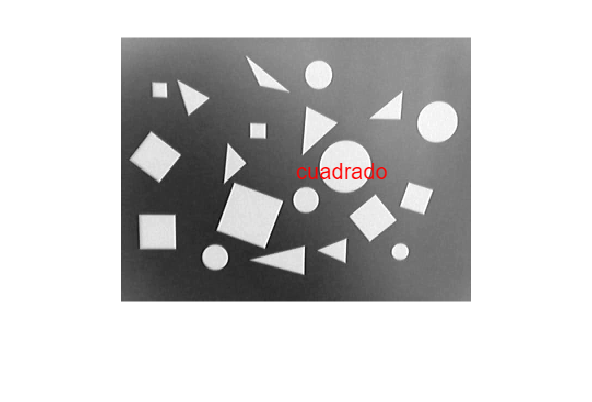

clasificar_figuras(256-nueva, dcitr, dcuci, dtrcu)   

nueva(1:40, 1:10)
img = 256-nueva;
img(1:40, 1:10)
imgb = imbinarize(img);
figure;
subplot(1,2,1); imshow(img, []);
subplot(1,2,2); imshow(img);

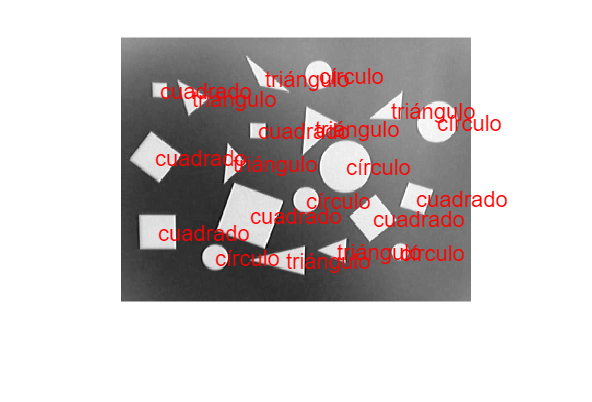

img = (256-nueva)/255;
[imgb, pro] = clasificar_figuras(img, dcitr, dcuci, dtrcu);

## INSPECCIÓN DE MEDICAMENTOS

Emplee el script ‘CargarMedicamentos’ para leer las imágenes (cap01 … cap15)

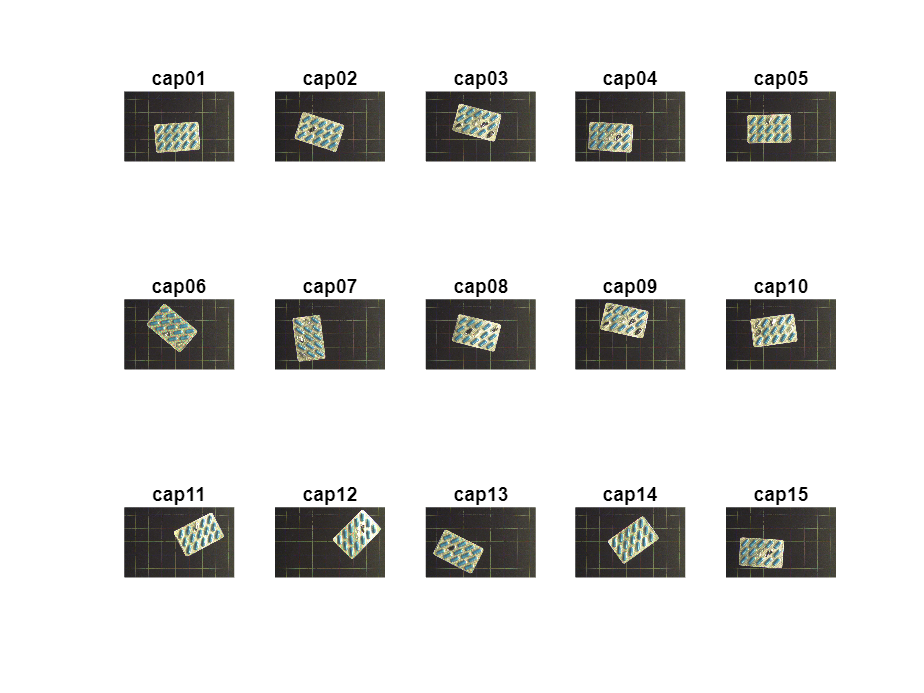

CargarMedicamentos

Desarrolle un programa en MatLab que tenga como entrada una imagen en color en la que aparezca un blister de medicamentos y que proporcione como salida una figura con tres imágenes: la imagen original, imagen de binarizada con solo las capsulas y una imagen en la que sólo aparezcan las capsulas en color, ademas esta imagen deberá indicar, en su título, si el blister está completo o no, y en el caso de no estarlo especificar el número de pastillas que le faltan. 

### Diseño

Una posible solución sería:

#### Mostrar imagen de entrada

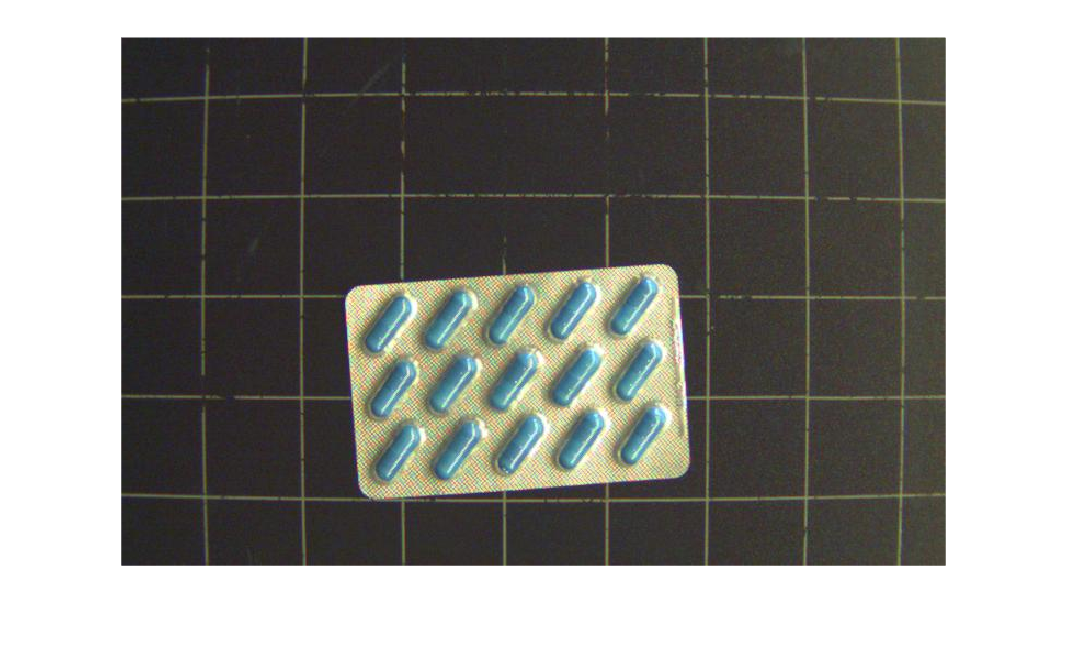

img = cap01;
figure
imshow(img)

#### Contador de cápsulas

capsulas = 0;
res = img(:,:, 1)==256;

#### Calcular imágenes S y H, rgb2hsv

imghsv = rgb2hsv(img);
H = imghsv(:, :, 1);
S = imghsv(:, :, 2);

#### Binarizar por matiz y color

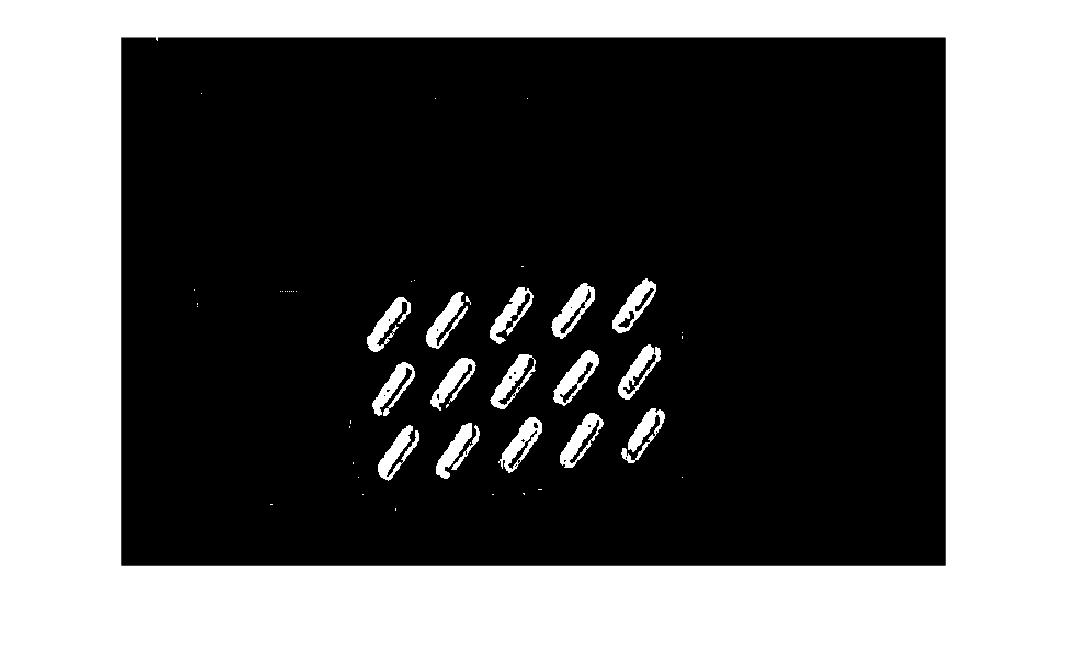

imgb = (S>0.3).*((H>0.5)&(H<0.6));
figure
imshow(imgb)

#### Mejora morfológica imb (una erosión y 4 dilataciones)

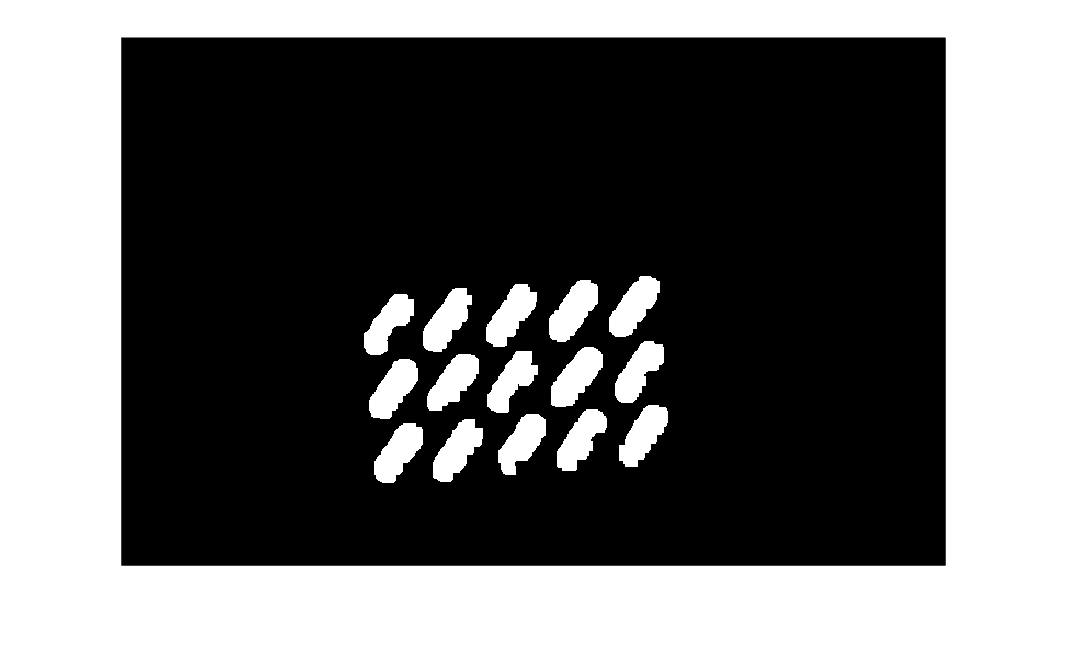

imgm = bwmorph(imgb, 'erode', 1);
imgm = bwmorph(imgm, 'dilate', 4);
figure
imshow(imgm);

#### Regiones conectadas de imb

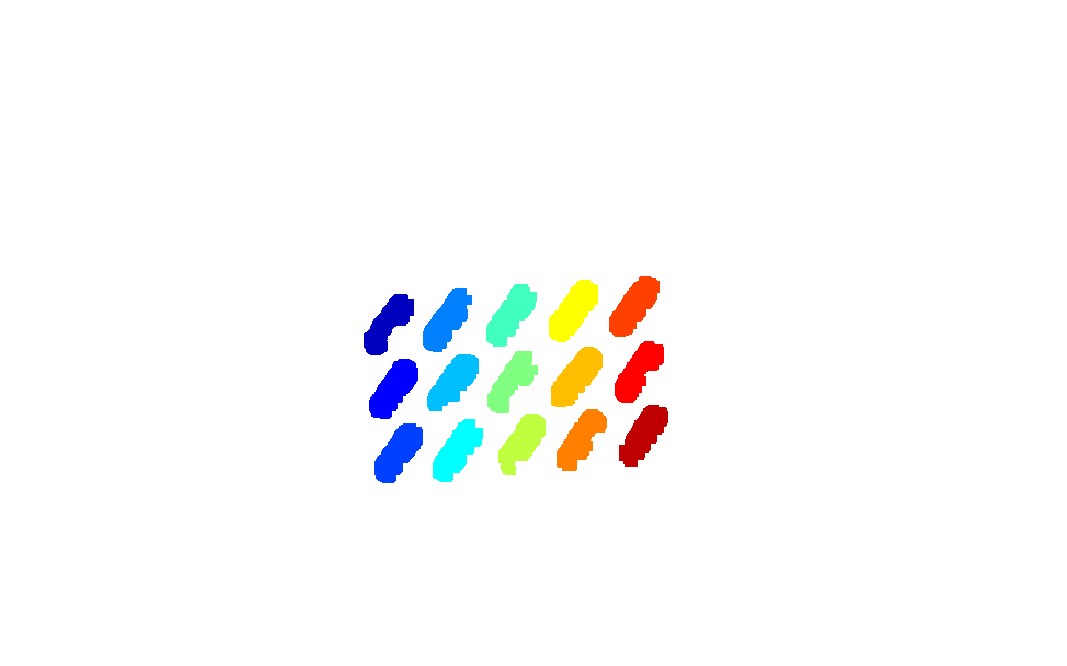

num_reg = 15

imgl = bwlabel(imgm);
figure;
imshow(label2rgb(imgl));

#### Regiones sin analizar?

num_reg = max(max(imgl))

capsulas = 2

#### Segmentar nueva región

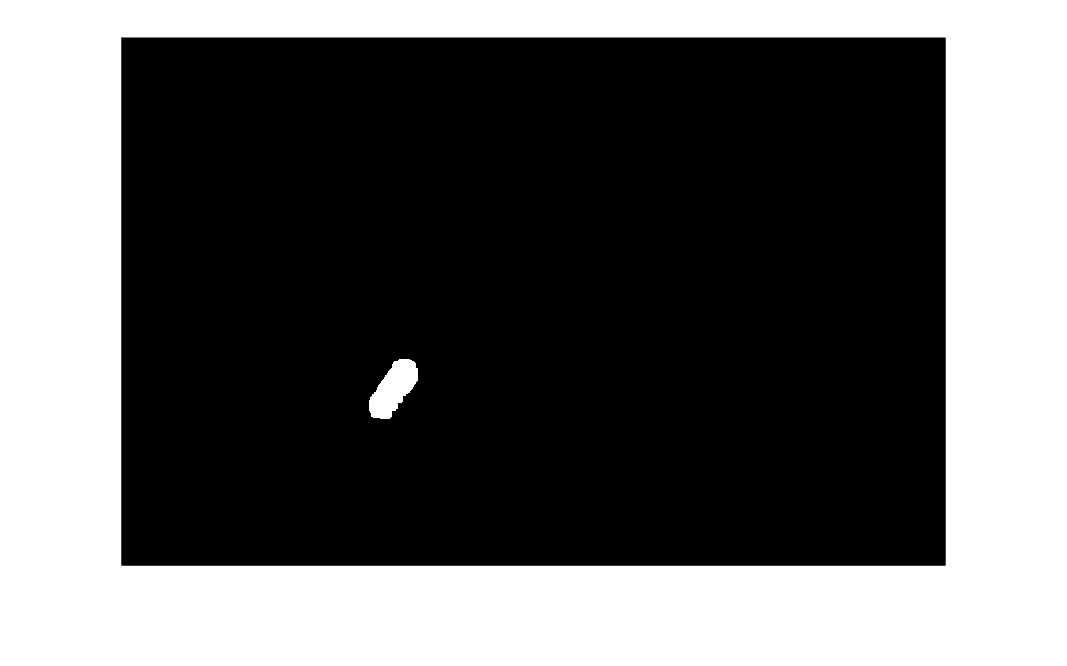

capsulas = capsulas +1
figure
imgb = imgl==capsulas;

imshow(imgb)

#### Calcular el área

area = bwarea(imgb)

area = 1.4552e+03

#### Si el área es mayor que 200...

if (area > 200) 
    capsulas = capsulas + 1; % incrementar el número de cápsulas    
    %img_r = img(:,:,1).*uint8(imgb);
    %img_g = img(:,:,2).*uint8(imgb);
    %img_b = img(:,:,3).*uint8(imgb);
    %img_rgb = cat(3, img_r, img_g, img_b); %imshow(rgbimage)
    %res = res + img_rgb; % [img(:,:,1).*imgd, img(:,:,2).*imgd, img(:,:,3).*imgd];
    res = res | imgb;
end
figure
imshow(res, []);

#### Si capsulas = 15...

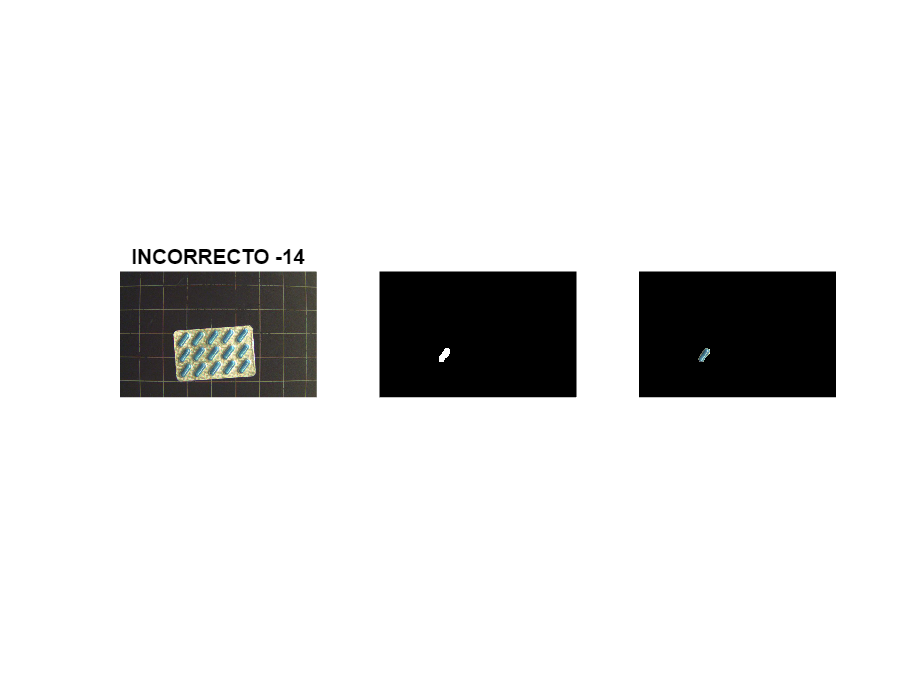

if capsulas == 15
    titulo = "CORRECTO";
else
    titulo = sprintf("INCORRECTO -%d",15-capsulas);
end
res = uint8(res);
img_r = img(:,:,1).*res;

img_g = img(:,:,2).*res;
img_b = img(:,:,3).*res;
img_rgb = cat(3, img_r, img_g, img_b);
figure
subplot(131); imshow(img); title(titulo);
subplot(132); imshow(res, []);
subplot(133); imshow(img_rgb, []);

### Codificación

### Pruebas

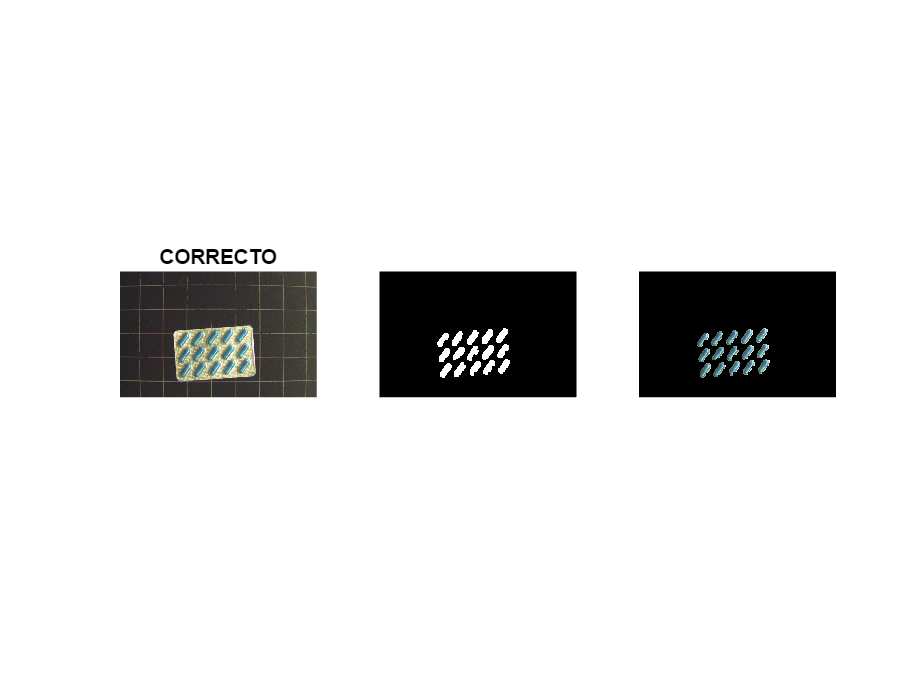

inspeccion_medicamentos(cap01)

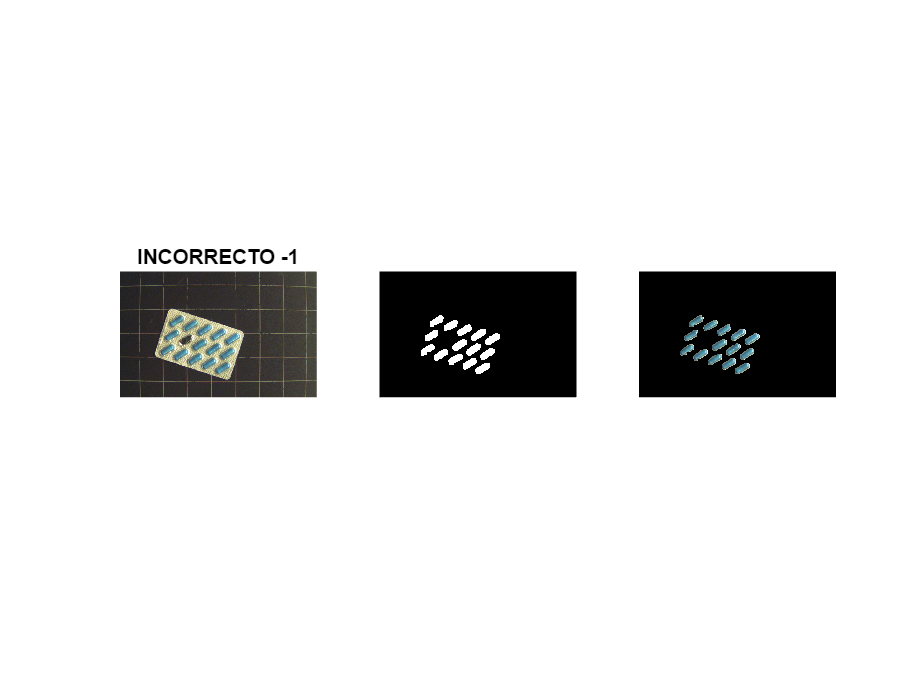

inspeccion_medicamentos(cap02)

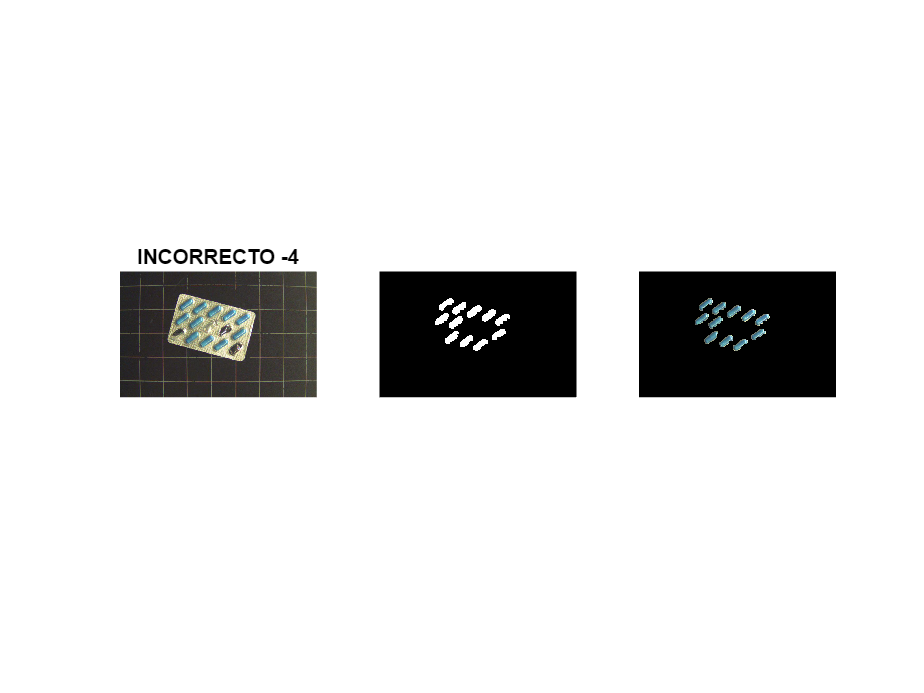

inspeccion_medicamentos(cap03)

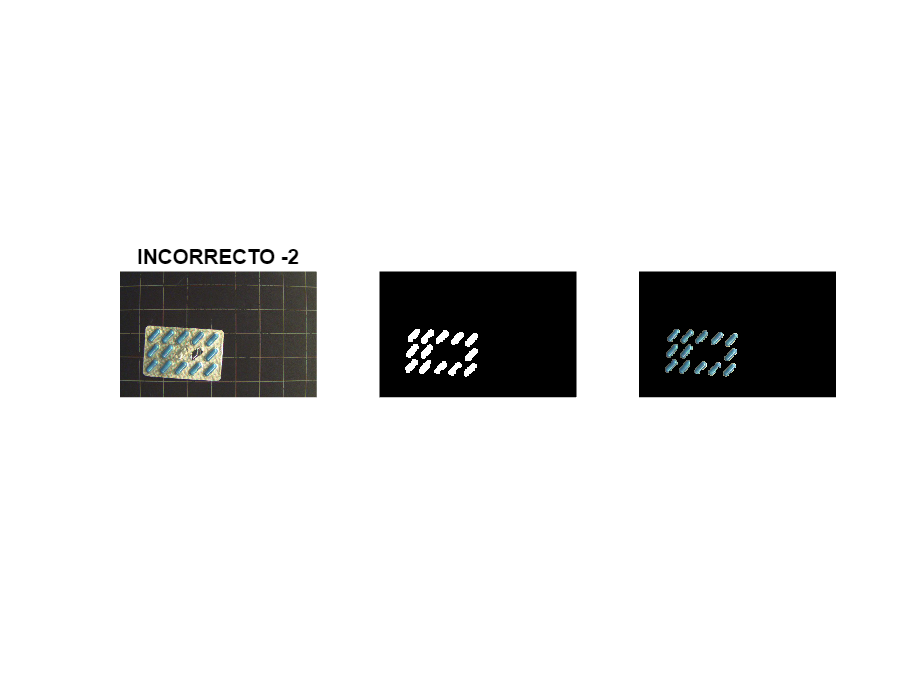

inspeccion_medicamentos(cap04)

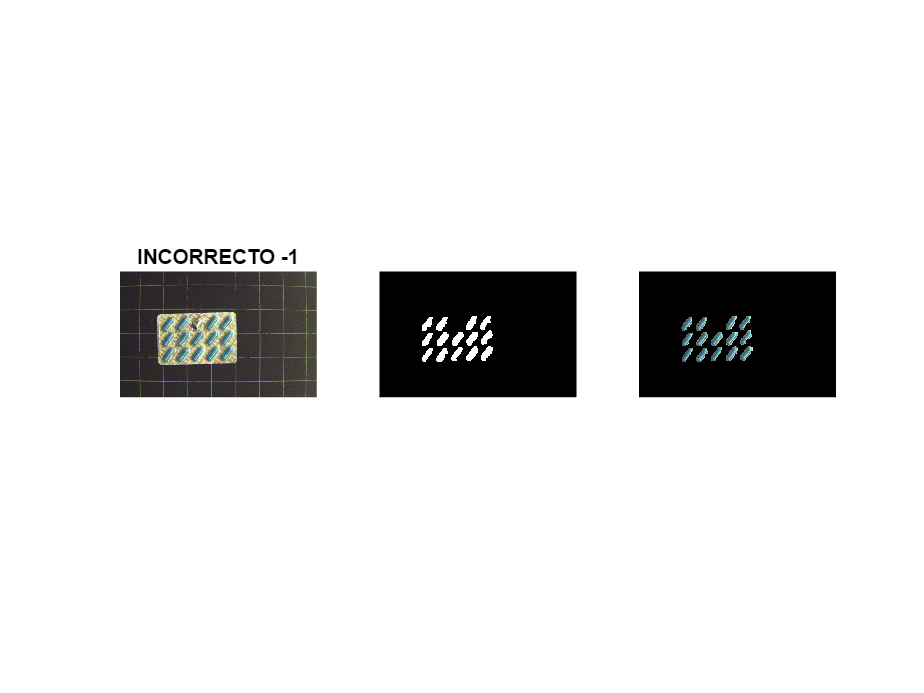

inspeccion_medicamentos(cap05)

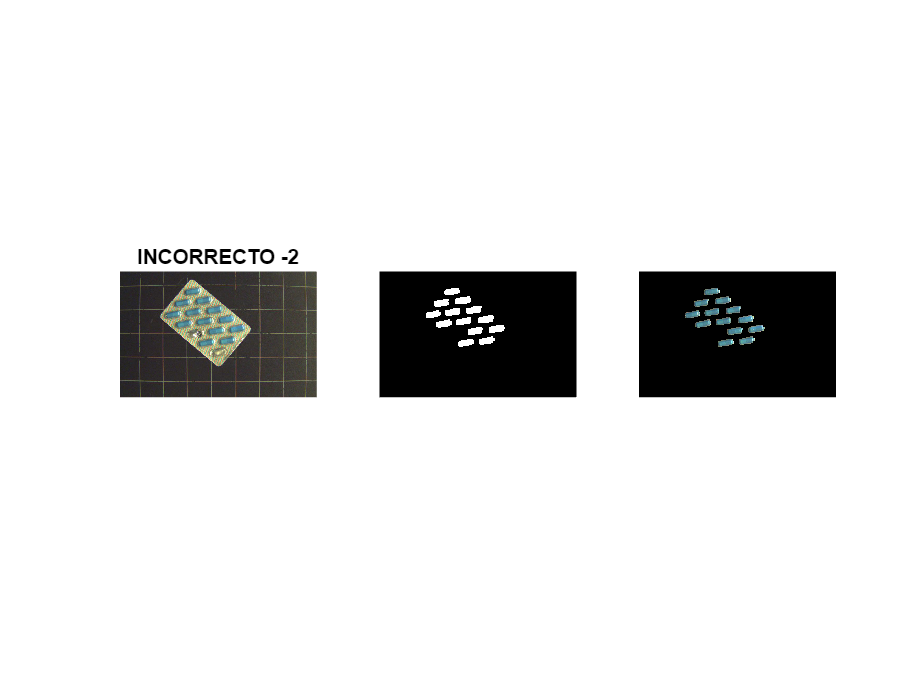

inspeccion_medicamentos(cap06)

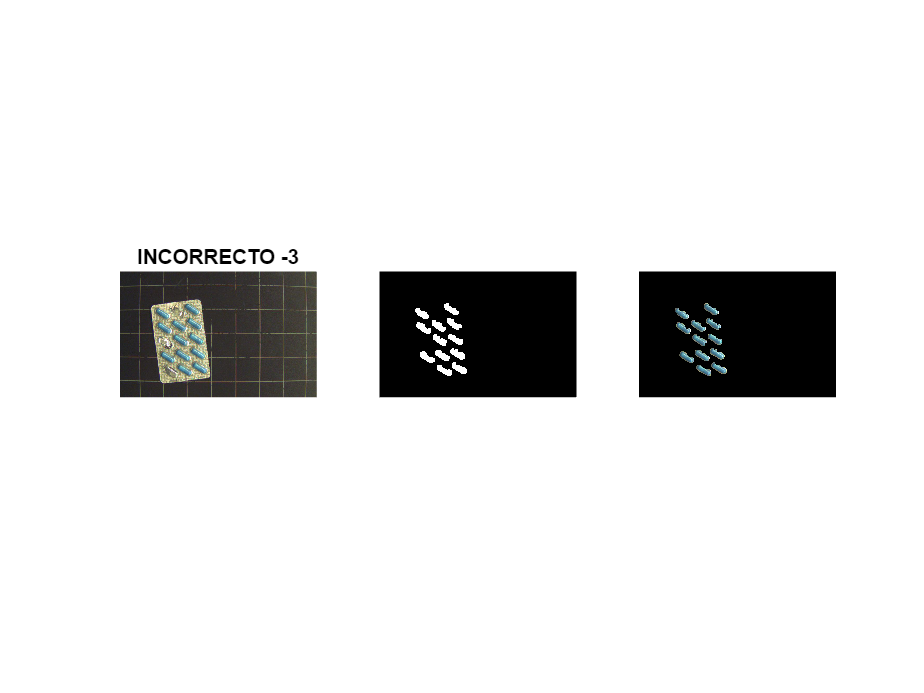

inspeccion_medicamentos(cap07)

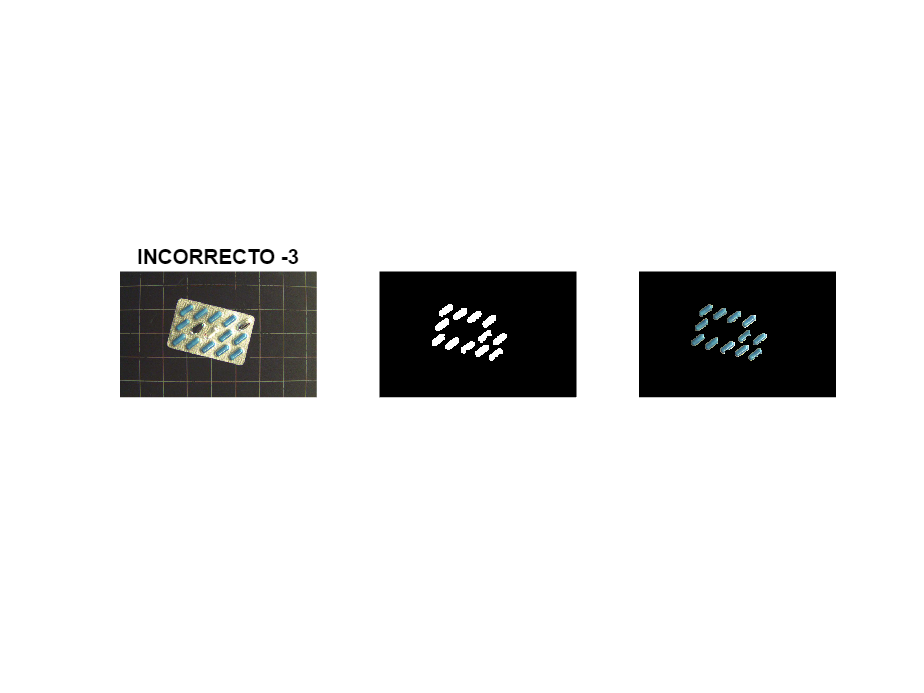

inspeccion_medicamentos(cap08)

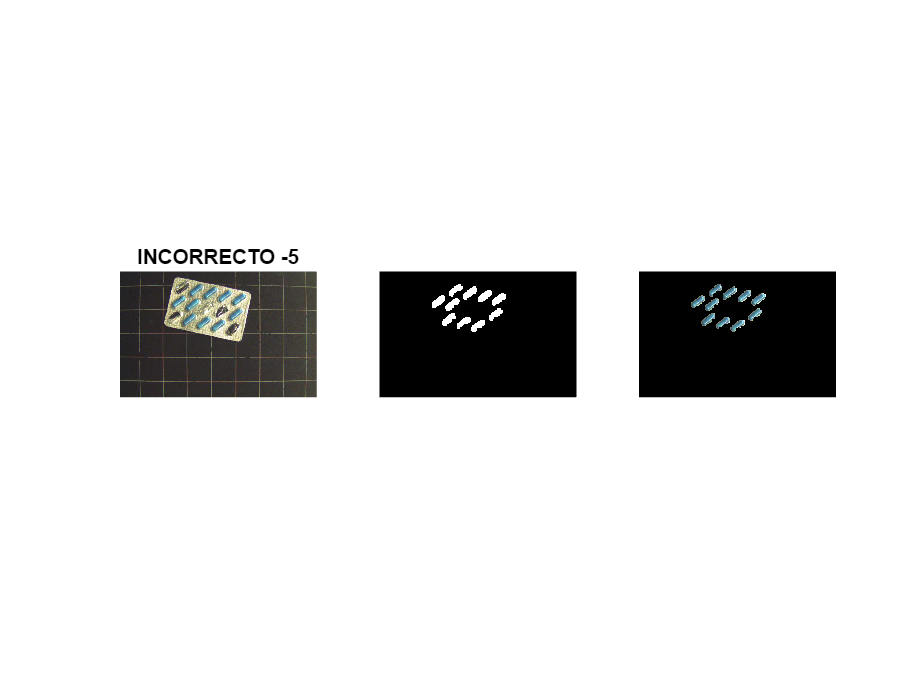

inspeccion_medicamentos(cap09)

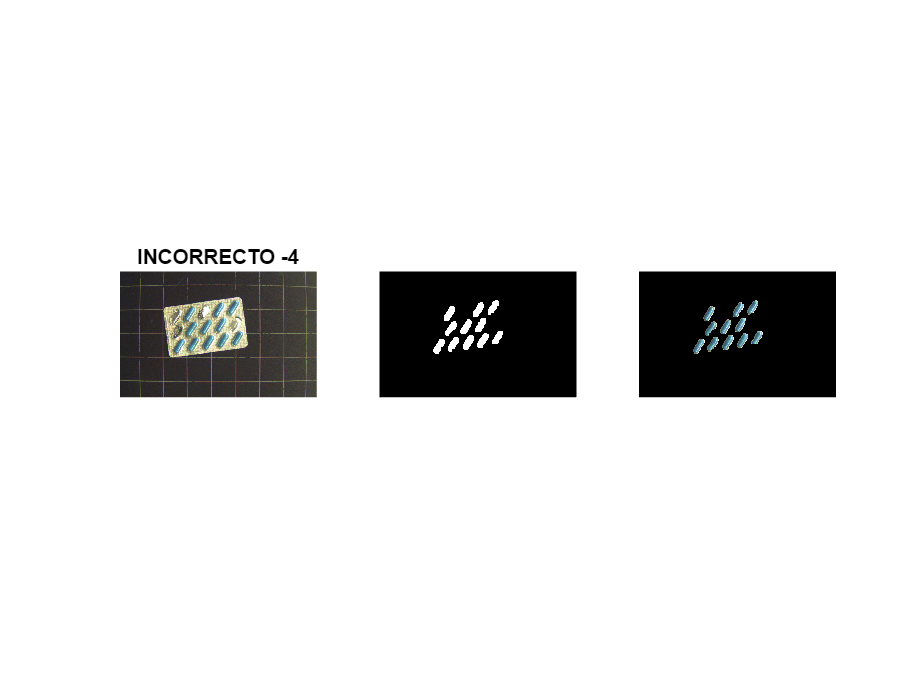

inspeccion_medicamentos(cap10)

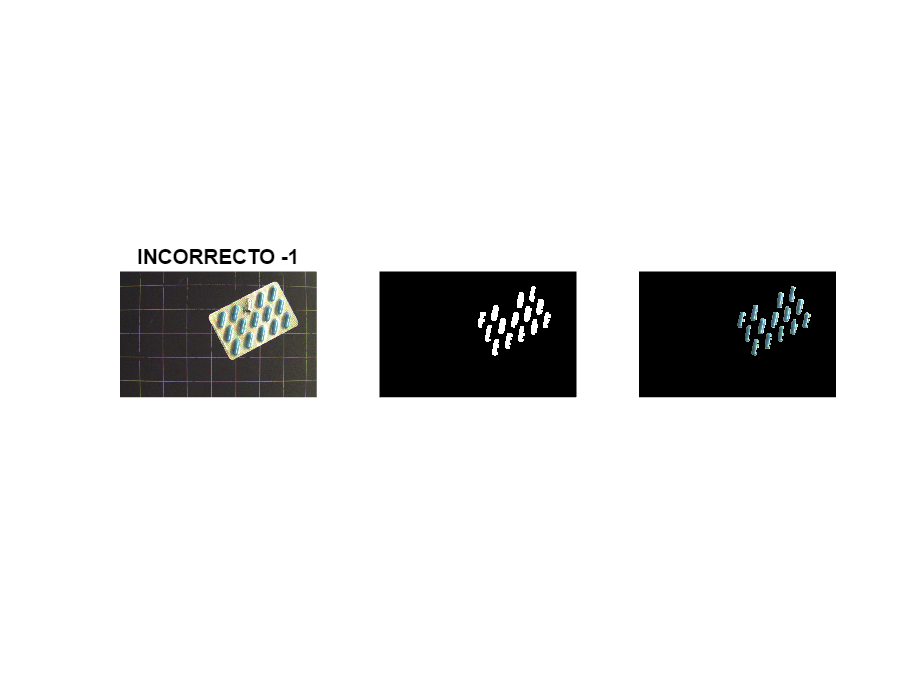

inspeccion_medicamentos(cap11)

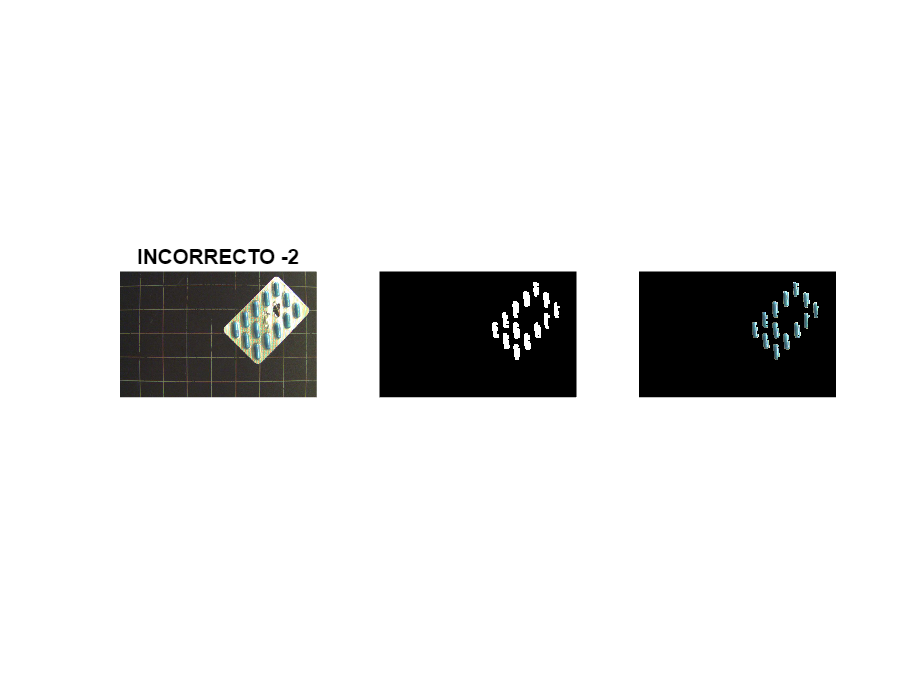

inspeccion_medicamentos(cap12)

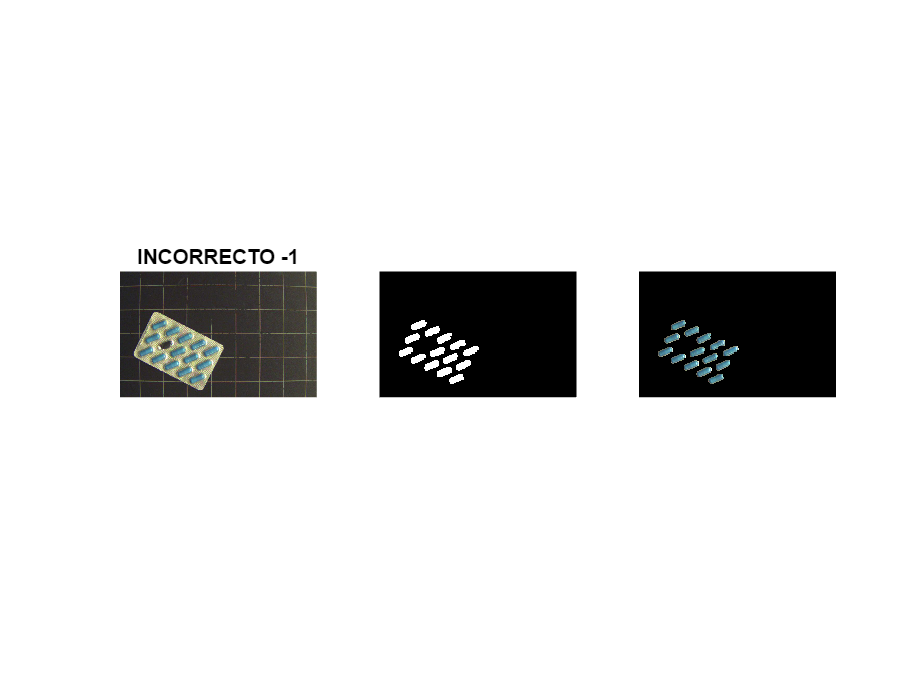

inspeccion_medicamentos(cap13)

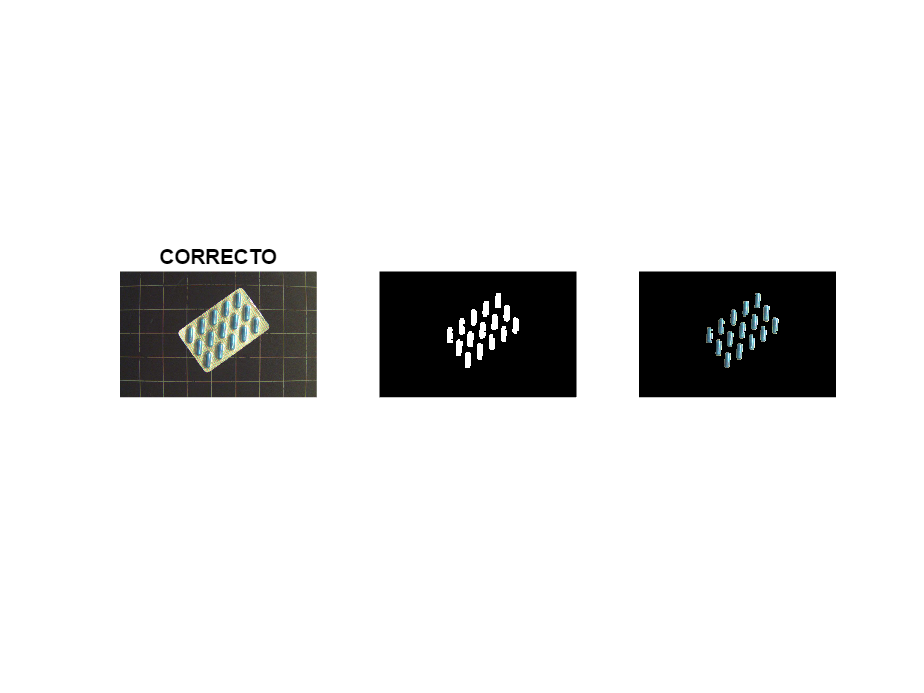

inspeccion_medicamentos(cap14)

inspeccion_medicamentos(cap15)

## EJERCICIO ADICIONAL

Como trabajo adicional puede realizar y entregar (mediante el campus virtual) este mismo programa, pero modificando la salida para que se marque, sobre la imagen original, donde faltan capsulas en el caso de que el blíster no esté completo.